clear
clc

num = [1 5]

num =      1     5


den = [6 5 1]

den =      6     5     1


G = tf(num, den)

G =
 
       s + 5
  ---------------
  6 s^2 + 5 s + 1
 
Continuous-time transfer function.



T_d = 1;
G_d = c2d(G,T_d,'zoh')

G_d =
 
    0.4273 z + 0.1303
  ----------------------
  z^2 - 1.323 z + 0.4346
 
Sample time: 1 seconds
Discrete-time transfer function.



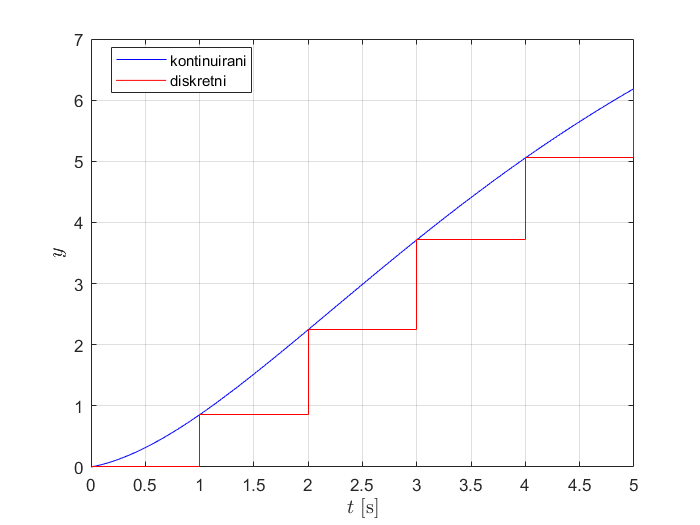


[num_d,den_d] = tfdata(G_d,'v');

% početni uvjeti
y_p1 = 0;
y_p2 = 0;
u_p1 = 0;
u_p2 = 0;

% broj točaka i priprema vektora za crtanje rezultata
N = 6;
y_d = zeros(N,1);
t_d = zeros(N,1);
u = 2;

for i = 1:N
    % rekurzivna relacija:
    y = 1.323*y_p1 - 0.4346*y_p2 + 0.4273*u_p1 + 0.1303*u_p2;
    % osvjezavanje vrijednosti u proslim koracima
    y_p2 = y_p1;
    y_p1 = y;
    u_p2 = u_p1;
    u_p1 = u;
    % punjenje vektora za crtanje rezultata
    y_d(i) = y;
    t_d(i) = (i-1)*T_d;
end

[y_k,t_k] = step(G,(N-1)*T_d);
plot(t_k,y_k*u,'b')
grid on
hold on
stairs(t_d,y_d,'r')
hold off
xlabel('$t$ [s]','interpreter','latex','fontsize',12)
ylabel('$y$','interpreter','latex','fontsize',12)
legend('kontinuirani','diskretni','location','best')